# Vehicle 1D Force App

The vehicle 1d force app visualizes the longitudinal vehicle force model. The model is used by the [Longitudinal Vehicle](https://www.mathworks.com/help/sdl/ref/longitudinalvehicle.html) block (Simscape Driveline).

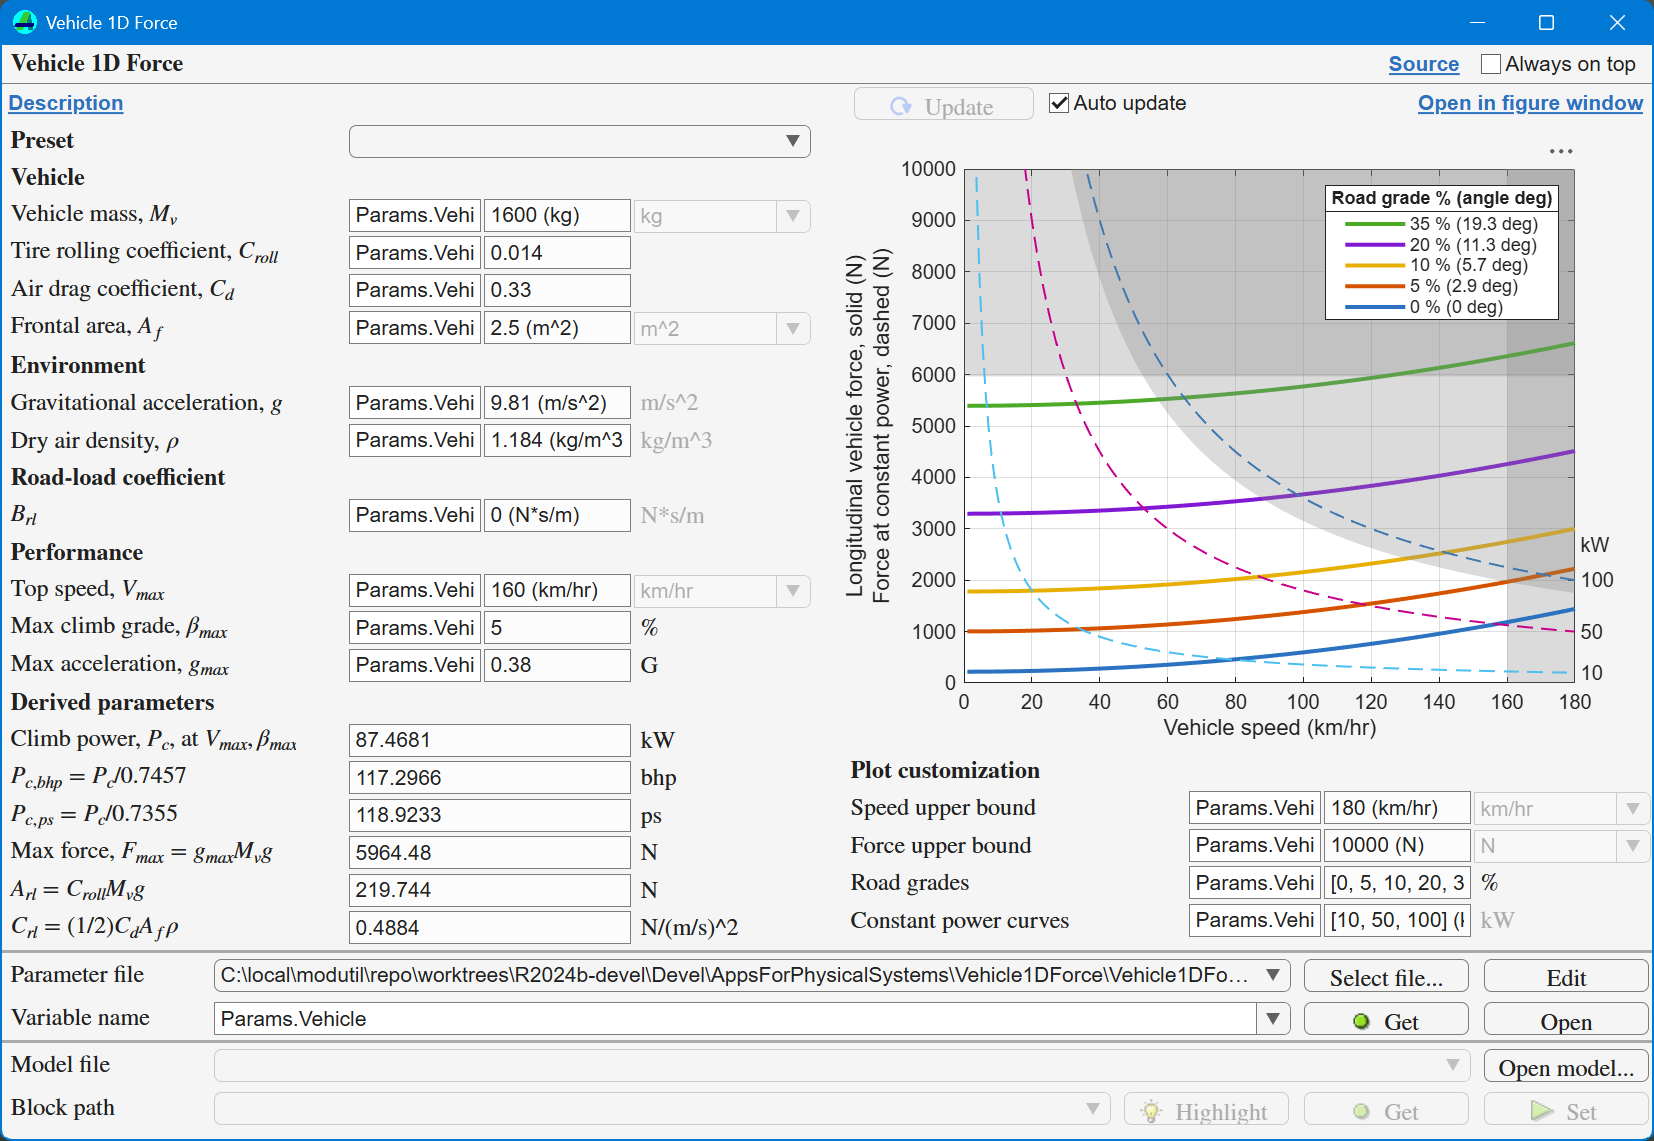

## Open the app

`Vehicle1DForceApp` opens the app.

`Vehicle1DForceApp(AppParameterFileName=<file_name>, AppParameterStructName=<struct_name>)` opens the app by first evaluating the specified `<file_name>` parameter file and then loading the specified `<struct_name>` struct from the base workspace to the app. These options correspond to the **Parameter file** and the **Variable name** in the app. The field names of the struct must match the app's parameter names as shown in the table.

For convenience, use `Vehicle1DForceAppParameters` to get predefined struct fields for a struct. For example, create a script as follows and save it as v`ehicle_parameters.m`.

Then open the app with the parameter file and the struct.

`Vehicle1DForceApp(AppParameterStructName=<struct_name>)` opens the app by reading the specified `<struct_name>` struct from the base workspace. The struct must exist in the base workspace.

`Vehicle1DForceApp(BlockPath=<block_path>)` opens the app by opening the specified model and loading block parameters from the specified vehicle block.

`Vehicle1DForceApp(ModelName=<model_name>)` opens the app by opening the specified model and loading block parameters from a block in the model. If there are more than two vehicle blocks, the first one is used.

## Programmatically visualize longitudinal vehicle force

Use `plotVehicle1DForcea` to create a plot programmatically. The app internally calls this function. The function supports two different ways to specify parameters using the `DataSource` option; `DataSource="direct"` or `DataSource="dataset"`.

The following is an example of using `DataSource="direct"`.

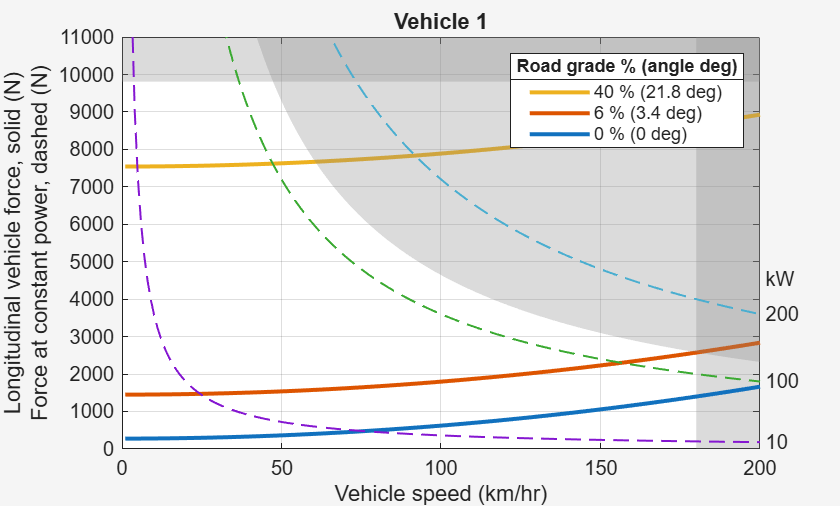

fig = Vehicle1DForce1.plotVehicle1DForce( ...
  DataSource = "direct", ...
  VehicleMass = simscape.Value(2000, "kg"), ...
  TireRollingCoefficient = 0.014, ...
  AirDragCoefficient = 0.33, ...
  GravitationalAcceleration = simscape.Value(9.81, "m/s^2"), ...
  DryAirDensity = simscape.Value(1.184, "kg/m^3"), ...
  RoadLoadB = simscape.Value(0, "N/(km/hr)"), ...
  TopSpeed = simscape.Value(180, "km/hr"), ...
  MaxAcceleration = 0.5, ...
  MaxClimbGradePercent = 6, ...
  PlotSpeedUpperBound = simscape.Value(200, "km/hr"), ...
  PlotForceUpperBound = simscape.Value(11000, "N"), ...
  PlotGrades = [0, 6, 40], ...
  PlotPowers = simscape.Value([10, 100, 200], "kW"), ...
  NumSpeedPoints = 200 );

% Example of specifying the title.
fig.CurrentAxes.Title.String = "Vehicle 1";

% Example of specifying the figure name. To see it, open the plot in a separate figure window.
fig.Name = fig.CurrentAxes.Title.String;

The following is an example of using `DataSource="dataset"`. In this case, first create a `Vehicle1DForceDataSet` object, specify parameters, update the object, and then pass it to the plot function.

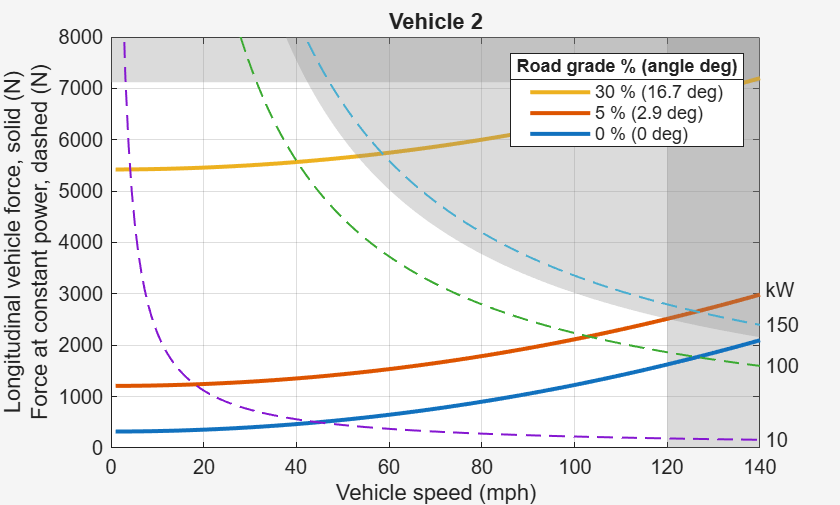

ds = Vehicle1DForce1.Vehicle1DForceDataSet;

ds.ModelParams.VehicleMass = simscape.Value(4000, "lbm");  % 4000 lbm = 1814 kg
ds.ModelParams.TireRollingRadius = simscape.Value(12, "in");  % 12 in = 30.48 cm
ds.ModelParams.TireRollingCoefficient = 0.018;
ds.ModelParams.AirDragCoefficient = 0.33;
ds.ModelParams.FrontalArea = simscape.Value(25, "ft^2");  % 25 ft^2 = 2.32 m^2
ds.ModelParams.GravitationalAcceleration = simscape.Value(9.81, "m/s^2");
ds.ModelParams.DryAirDensity = simscape.Value(1.184, "kg/m^3");
ds.ModelParams.RoadLoadB = simscape.Value(0, "N/(km/hr)");
ds.ModelParams.TopSpeed = simscape.Value(120, "mph");
ds.ModelParams.MaxAcceleration = 0.4;
ds.ModelParams.MaxClimbGradePercent = 5;

ds.PlotSpeedUpperBound = simscape.Value(140, "mph");
ds.PlotForceUpperBound = simscape.Value(8000, "N");
ds.PlotGrades = [0, 5, 30];
ds.PlotPowers = simscape.Value([10, 100, 150], "kW");
ds.NumSpeedPoints = 200;

% Update internal states including derived parameters.
ds = updateDataSet(ds);

fig = Vehicle1DForce1.plotVehicle1DForce(DataSource="dataset", DataSet=ds);
fig.CurrentAxes.Title.String = "Vehicle 2";

By using the data set, you can access internal information including derived parameters.

ds.ModelParams.RoadLoadA

ans =   320.3814 (N)


ds.ModelParams.RoadLoadC

ans =     0.4537 (N*s^2/m^2)


ds.ModelParams.MaxForce

ans =    7.1196e+03 (N)


ds.ModelParams.MaxClimbPower

ans =   134.8937 (kW)


Below is an example of obtaining the power in brake horsepower (bhp) or in metric horsepower (ps).

% Brake horsepower (imperial)
pm_addunit("bhp", 745.7, "W")
convert(ds.ModelParams.MaxClimbPower, "bhp")

ans =   180.8954 (bhp)


% Metric horsepower (Pferdestärke)
pm_addunit("ps", 735.5, "W")
convert(ds.ModelParams.MaxClimbPower, "ps")

ans =   183.4041 (ps)


*Copyright 2026 The MathWorks, Inc.*